clear all 
close all
A=imread('rankfiltered.jpg');

size(A)

ans =    512   512     3


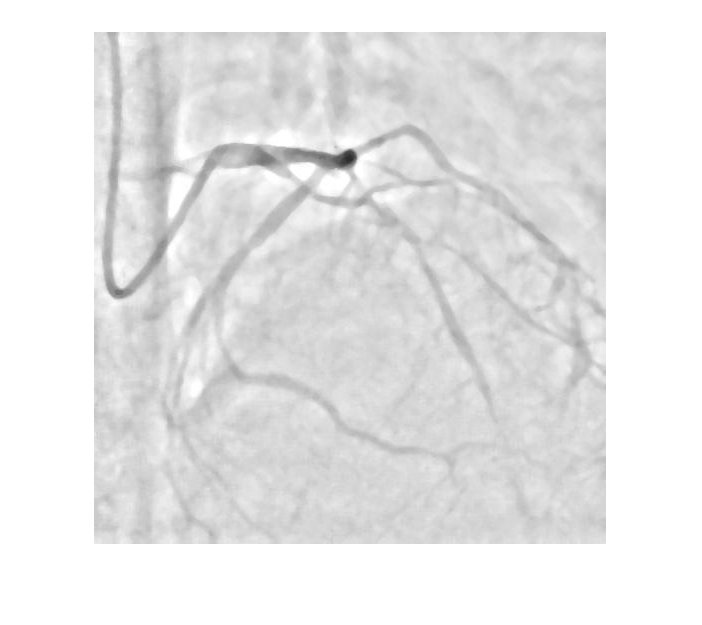

imshow(A)

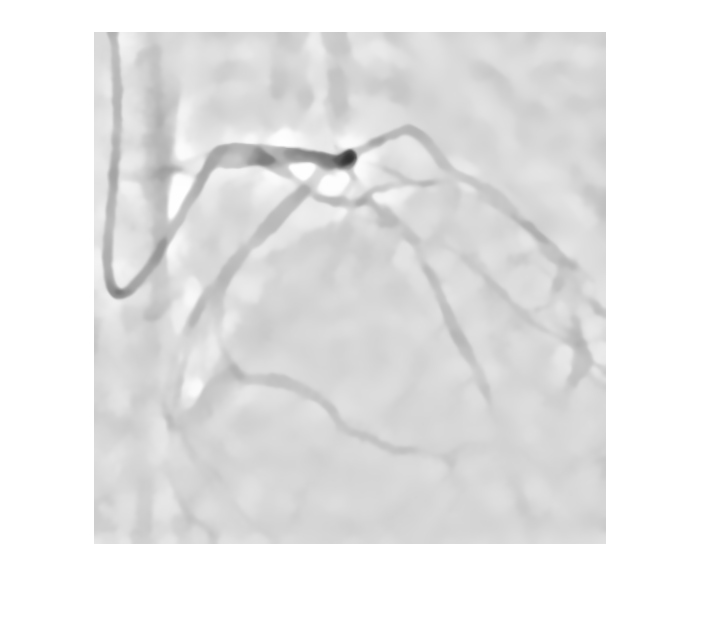

noisyLAB = rgb2lab(A);
roi = [210,24,52,41];
patch = imcrop(noisyLAB,roi);
patchSq = patch.^2;
edist = sqrt(sum(patchSq,3));
patchSigma = sqrt(var(edist(:)));
DoS = 1.1*patchSigma;
denoisedLAB = imnlmfilt(noisyLAB,'DegreeOfSmoothing',DoS);
denoisedRGB = lab2rgb(denoisedLAB,'Out','uint8');
A=rgb2gray(denoisedRGB);
imshow(denoisedRGB);


% A=ordfilt2(A,5,ones(3,3));
% %i=rgb2gray(j);
% AInv = imcomplement(A);
% 
% BInv = imreducehaze(AInv);
% B = imcomplement(BInv);
% BInv = imreducehaze(AInv,0.9, 'Method','approx','ContrastEnhancement','boost');
% 
% BImp = imcomplement(BInv);
% figure, montage({A BImp});
% A=adapthisteq(BImp);



Harris

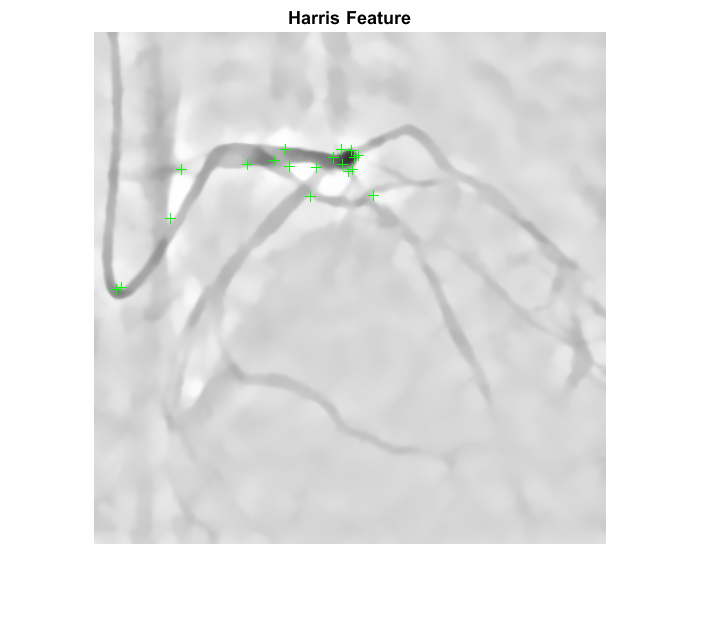

c=detectHarrisFeatures(A);
[~,var]=extractFeatures(A,c);
imshow(A);hold on
plot(var.selectStrongest(50))
title("Harris Feature")

SURF

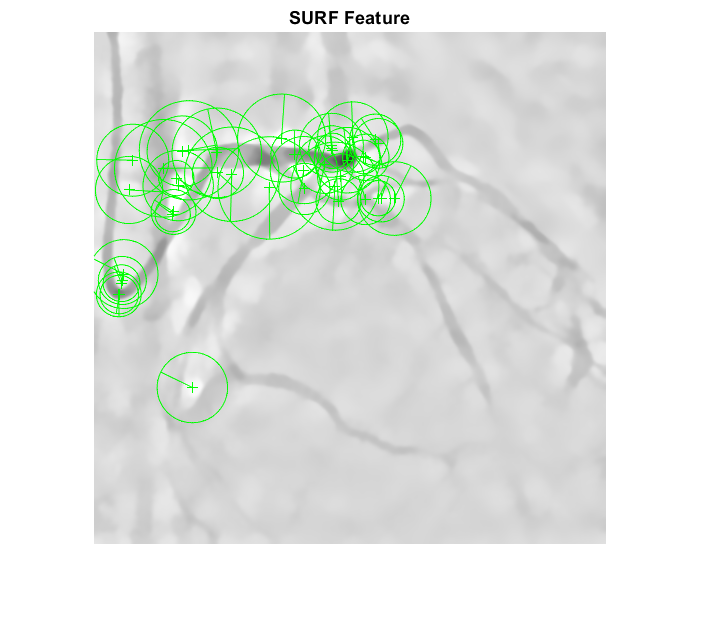

pt=detectSURFFeatures(A);
[~,var]=extractFeatures(A,pt);
figure,imshow(A),hold on
plot(var.selectStrongest(50),"ShowOrientation",true);
title("SURF Feature")

MSER

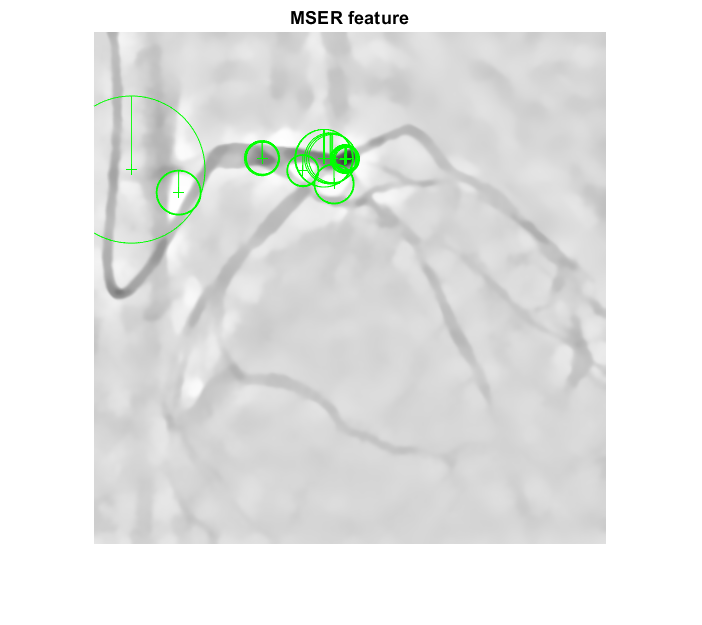

reg=detectMSERFeatures(A);
[f,var]=extractFeatures(A,reg,'Upright',true);
figure,imshow(A),hold on;
plot(var,'ShowOrientation',true);
title("MSER feature")

KAZE

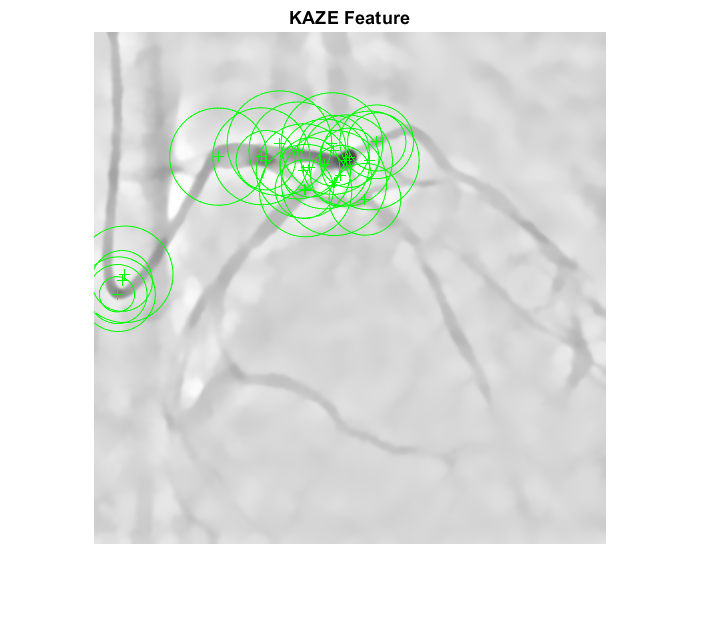

pt=detectKAZEFeatures(A);
st=selectStrongest(pt,25);
figure,imshow(A),hold on;
plot(st);
title("KAZE Feature");

BRISK

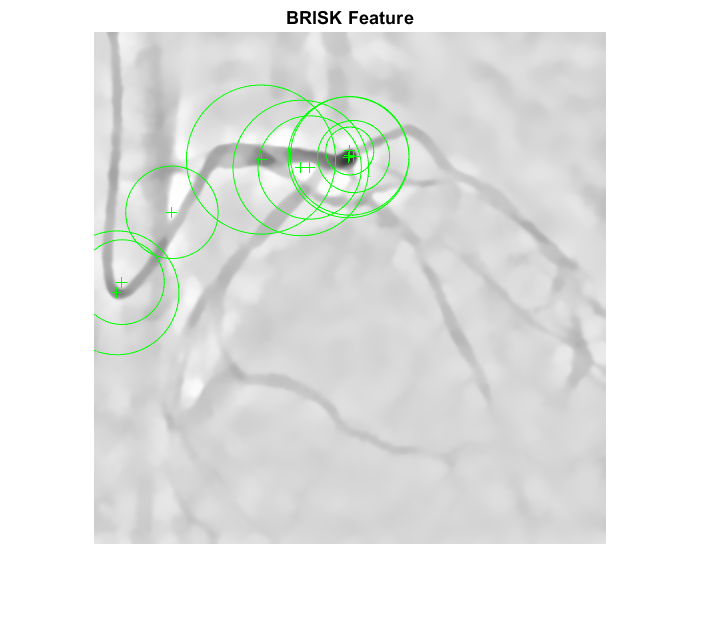

pt=detectBRISKFeatures(A);
st=selectStrongest(pt,25);
figure,imshow(A),hold on;
plot(st);
title("BRISK Feature");

function [outImg]=gray2d(bw)
[r, c]=size(bw);
bw=imresize(bw,[r,c]);

 for x=1:3;
    for i=1:r
       for j=1:c
           outImg(i,j,x)=bw(i,j);
       end
    end
 end
end

function [outImg]=bi2gray(bw)
[r, c]=size(bw);

outImg=ones([r c]);
for i=1:r
    for j=1:c
        if bw(i,j)==1;
            outImg(i,j)=255;
        else
            outImg(i,j)=0;
        end
    end
end
end



